## Transistor circuits

ELABorate can handle transistors by modelling them using an appropriate set of linear elements.

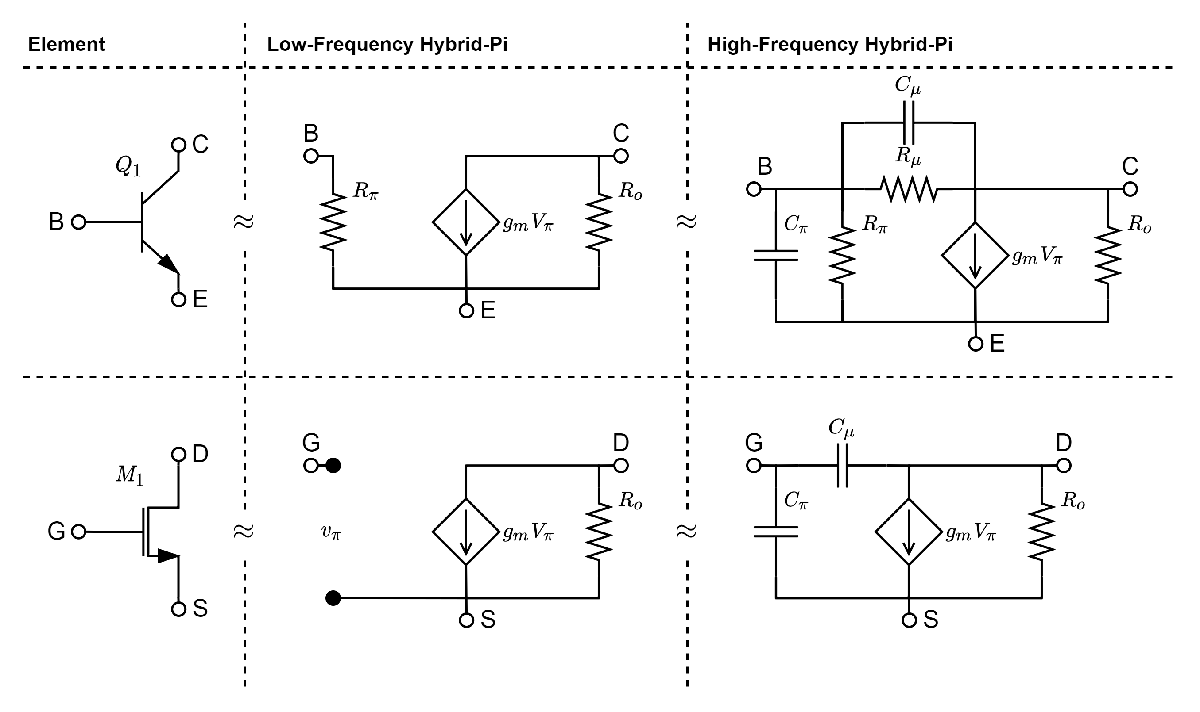

### 1. BJTs

We start by loading in a circuit containing a BJT. In this case, it's a simple common-source amplifier with biasing.

circuit = Circuit('circuits/amplifiers/bjts/c1_bjt_cs_amp.txt');
circuit.list

ans =     'VBB 0 1 DC VBB
     VCC 5 0 DC VCC
     Vi 1 2 AC Vi
     RB 2 3 RB
     RC 4 5 RC
     Q1 3 4 0 beta_Q1
     '


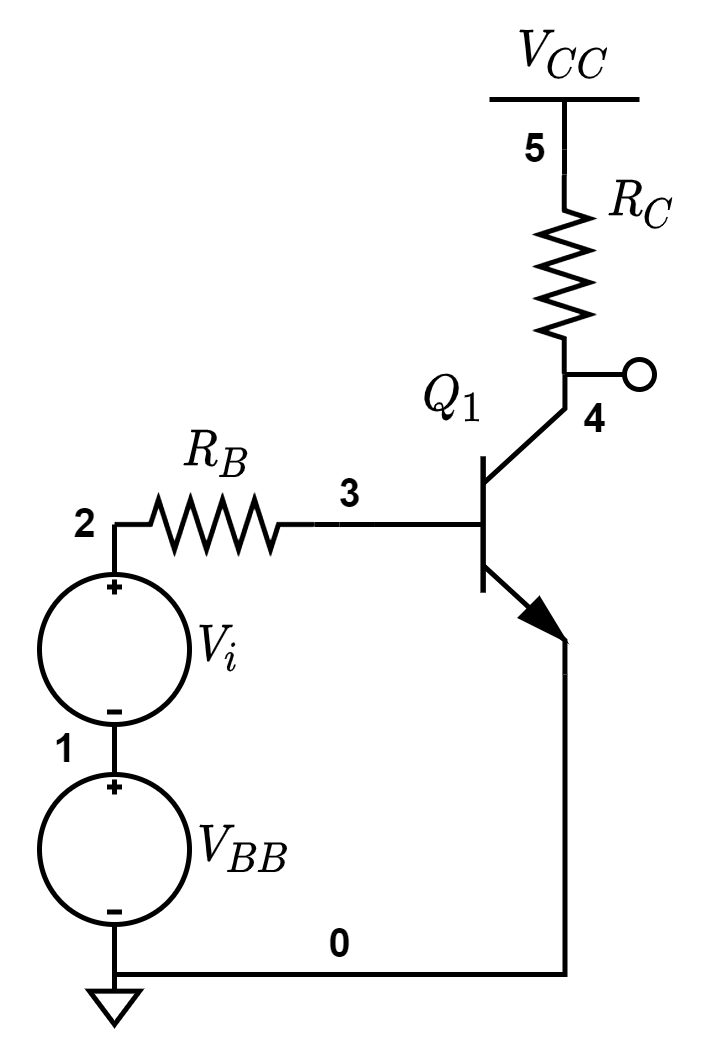

Typically, when analyzing such circuits, we split up the analysis into a DC-part and an AC-part. To find the DC-equivalent of the circuit above, one can simply call the `dc_eq` function (short for *direct-current-equivalent*). This function uses lower-level functions such as `short`, `open` and `clean` to modify the given circuit into its DC-equivalent.

ELAB.dc_eq(circuit);
circuit.list

ans =     'VBB 0 1 DC VBB
     VCC 4 0 DC VCC
     RB 1 2 RB
     RC 3 4 RC
     Q1 2 3 0 beta_Q1
     '


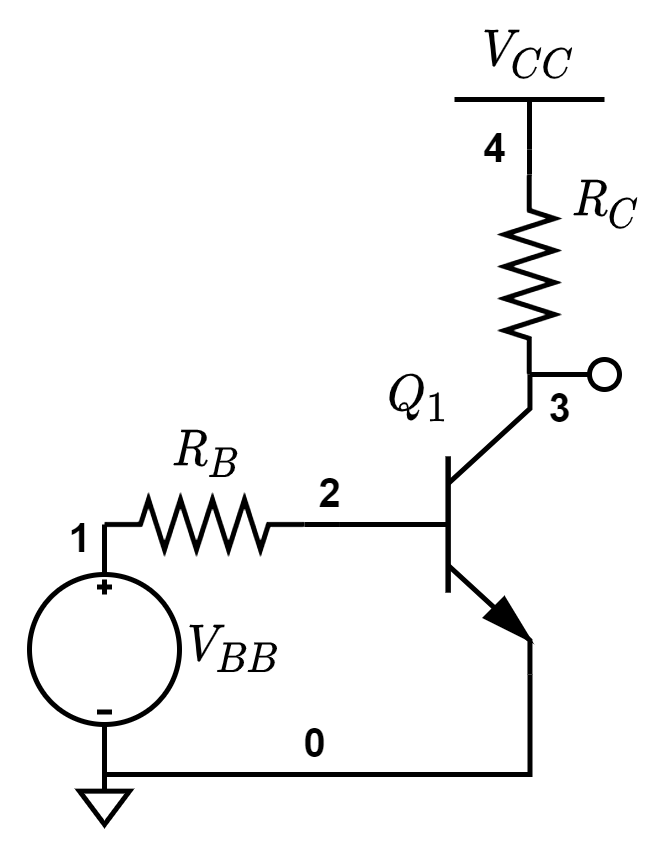

Similarly, the program can convert the given circuit into its AC-equivalent.

circuit = Circuit('circuits/amplifiers/bjts/c1_bjt_cs_amp.txt');
ELAB.ac_eq(circuit);
circuit.list

ans =     'Vi 0 1 AC Vi
     RB 1 2 RB
     RC 3 0 RC
     Q1 2 3 0 beta_Q1
     '


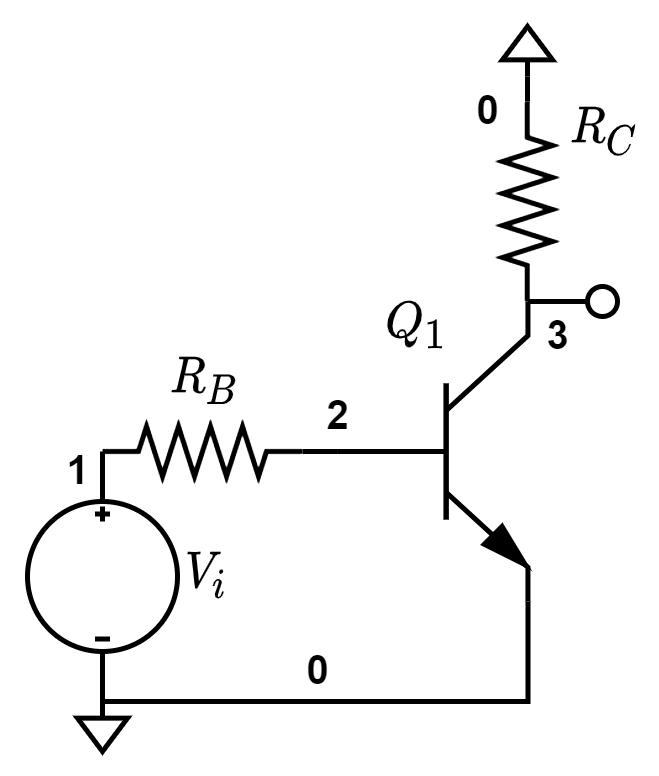

From the AC-equivalent, you can model the transistor as linear elements, using the `hpi` (hybrid-pi) function, which can either assume the circuit will operate in low-frequency "`lf`" or high-frequency "`hf`". We can use the `clone` function to preserve the AC-equivalent.

lf_circuit = circuit.clone;
ELAB.hybrid_pi(lf_circuit,'lf');
lf_circuit.list

ans =     'Vi 0 1 AC Vi
     RB 1 2 RB
     RC 3 0 RC
     R_pi_Q1 2 0 R_pi_Q1
     R_o_Q1 3 0 R_o_Q1
     G_m_Q1 3 0 0 2 G_m_Q1
     '


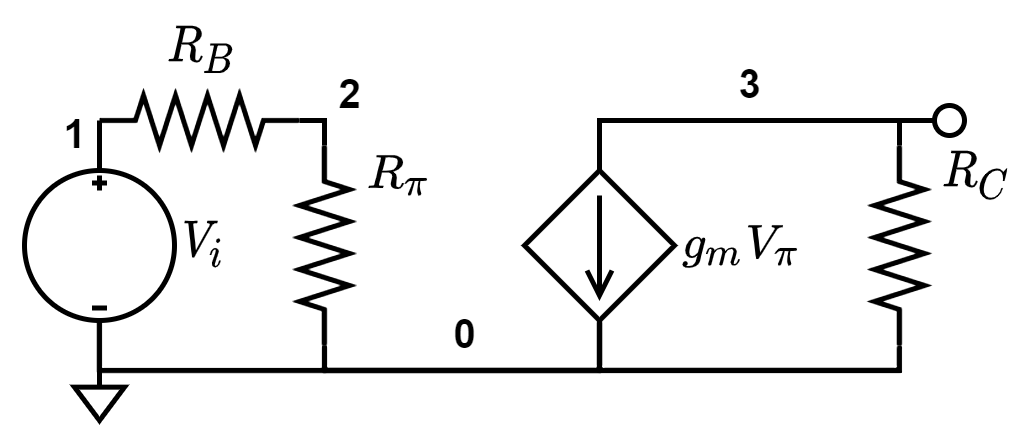

hf_circuit = circuit.clone;
ELAB.hybrid_pi(hf_circuit,'hf');
hf_circuit.list

ans =     'Vi 0 1 AC Vi
     RB 1 2 RB
     RC 3 0 RC
     R_pi_Q1 2 0 R_pi_Q1
     R_o_Q1 3 0 R_o_Q1
     R_mu_Q1 2 3 R_mu_Q1
     C_pi_Q1 2 0 C_pi_Q1
     C_mu_Q1 2 3 C_mu_Q1
     G_m_Q1 3 0 0 2 G_m_Q1
     '


### 2. MOSFETs

All the same functionality exists for circuits containing MOSFET transistors. To illustrate this, we load in this circuit.

circuit = Circuit('circuits/amplifiers/mosfets/c1_mos_cs_amp.txt');
circuit.list

ans =     'Vi 1 0 AC Vi
     VDD 3 0 DC VDD
     RD 2 3 RD
     RG 1 2 RG
     RL 2 0 RL
     M1 1 2 0 100
     '


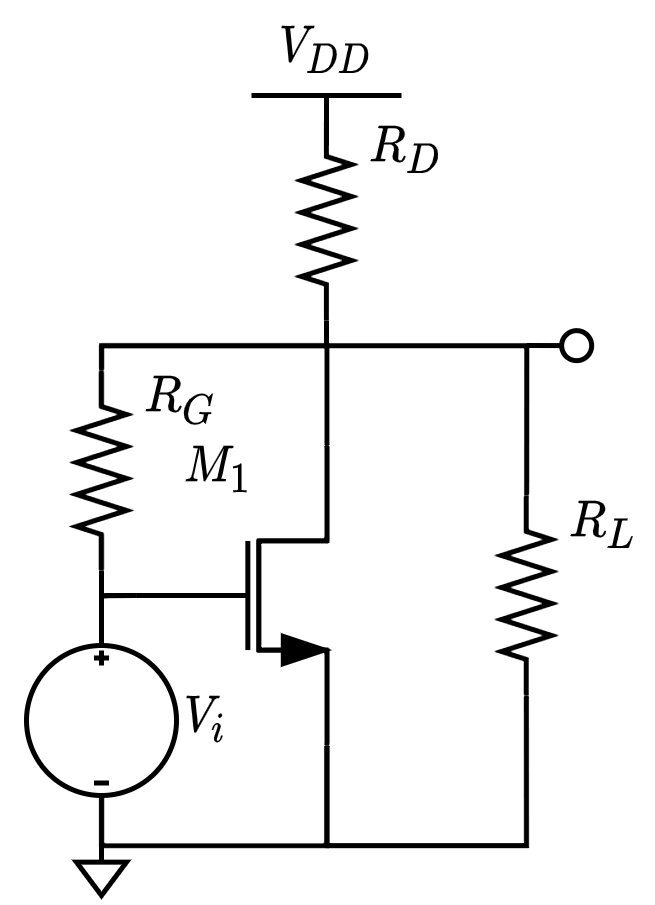

ELAB.hybrid_pi(circuit,'lf');
circuit.list

ans =     'Vi 1 0 AC Vi
     RD 2 0 RD
     RG 1 2 RG
     RL 2 0 RL
     R_o_M1 2 0 R_o_M1
     G_m_M1 2 0 0 1 G_m_M1
     '


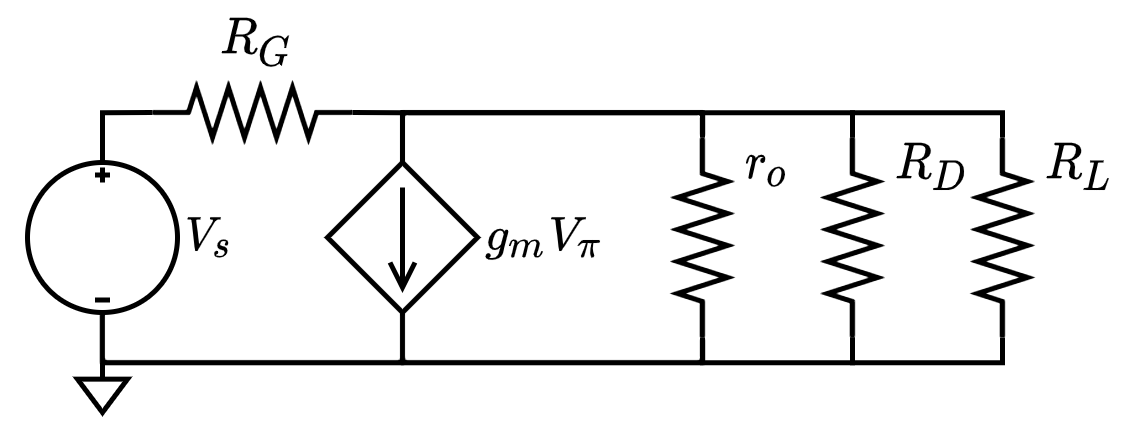

As this circuit contains three resistors in parallel, we may want to simplify the circuit for further analysis.

ELAB.simplify(circuit);
circuit.list

ans =     'Vi 1 0 AC Vi
     RG 1 2 RG
     Req1 2 0 (RD*RL*R_o_M1)/(RD*RL + RD*R_o_M1 + RL*R_o_M1)
     G_m_M1 2 0 0 1 G_m_M1
     '
